# Bootstrap sampling

This Notebook aims to show a tecnique used in statistics called bootstrapping. 

The example is based on Spiegelhalter, David. 2019. The Art of Statistics: Learning from Data, Pelican Books, ISBN 978-0241398630., [dspiegel29/ArtofStatistics: Code for 'The Art of Statistics' (github.com)](https://github.com/dspiegel29/ArtofStatistics/tree/master)

Copyright (c) 2019 David Spiegelhalter

Permission is hereby granted, free of charge, to any person obtaining a copy

of this software and associated documentation files (the "Software"), to deal

in the Software without restriction, including without limitation the rights

to use, copy, modify, merge, publish, distribute, sublicense, and/or sell

copies of the Software, and to permit persons to whom the Software is

furnished to do so, subject to the following conditions:

### Introduction

Suppose we have results from an important survey, for example asking a qestion to a sample of 1000 people, and we want to tell the world what is the main outcome  the survey. The first approach that comes to mind is to just share the most common statistics like the sample mean or the sample median and state that that is the average value for the entire population. Now, the question is:  How much the sample mean is close to the population mean? 

Chapter 7 of (Spiegelhalter, 2019) called "How sure can we be about what is going on?" tries to answer this question introducing a tecnique called Bootstrapping. This topic gently introduces the reader to the important topic of the Central Limit Theorem. 

Intuitively, the more is the sample size big, the more the sample mean gets close to the population mean. However, including in a survey an entire country population is obviously not practically possible hence we need to come up with some statistical tecnique. 

The main idea of Bootstrapping is  simple: from the initial sample of N observations we extract K new samples with replacement. Hence we ends up with K new samples {*sample1*, *sample2*, ..*.sampleK*}. For each new kth sample we calclate its mean and so we will have a sample of means. If the variance of this new distribution of means is low, then we can say that the mean of the initial sample (of size N) was accurate. Instead, if the variance of this new distribution of means is big, then something in the initial sample migh be wrong. 

In other words, the probability distribution of the means of the new samples helps us understand the uncertainty on the initial sample mean. 

Let's see a simple example. 

Suppose we have an initial sample from a survey that asked to 796 people how many partners they had in their life. The full dataset with a more detailed description is available on [Spiegelhalter, 2019](http://dspiegel29/ArtofStatistics:%20Code%20for%20'The%20Art%20of%20Statistics'%20(github.com)). 

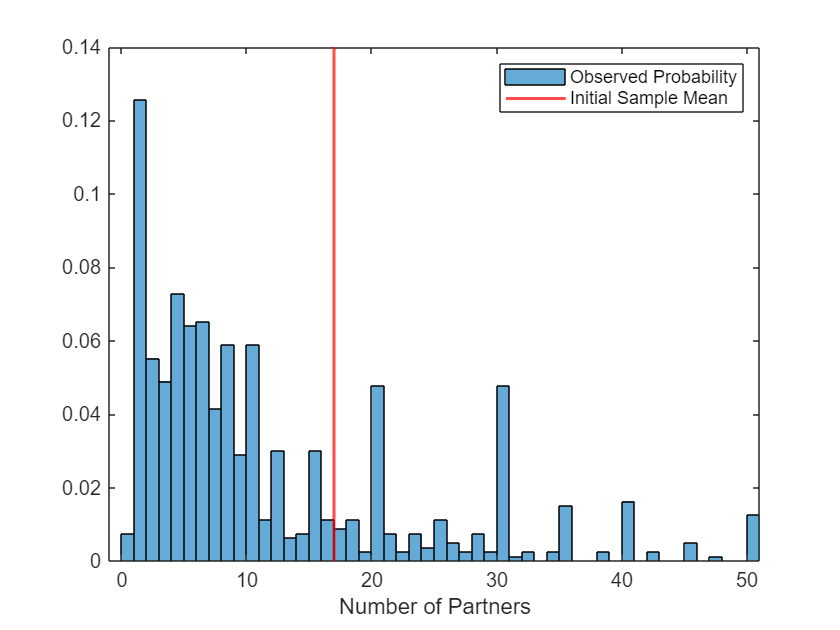

load data
sampleSize = numel(initialSample); 
histogram(initialSample,sampleSize,"Normalization","probability", DisplayName="Observed Probability",BinWidth=1)
xline(mean(initialSample), "red", "LineWidth",1.5, DisplayName="Initial Sample Mean")
xlabel("Number of Partners"), xlim([-1 51]), legend

The Initial Sample Mean (red line on the histogram plot) is 

InitialSampleMean= mean(initialSample)

InitialSampleMean = 16.9786

Recall the question we want to answer is: how close is this mean to the population mean? 

### Data Bootstrap

From the Initial sampe we generate K new samples (with replacement!) and for each new sample we compute its mean. This operation could be easily implemented writing some code or just by calling the [bootstrp](https://www.mathworks.com/help/stats/bootstrp.html) MATLAB function. 

rng('default')  % For reproducibility
K = 100; 
newMeans = bootstrp(K,@mean,initialSample)

newMeans =    16.0402
   15.9824
   18.4246
   17.0276
   17.4410
   15.8794
   14.4209
   16.2048
   17.3342
   17.8103


Now we have K new samples (randomly drawn from the initial sample with replacement) and K new means (one for each new samlpe). 

Let's create an histogram to visualize the distribution of the new means. 

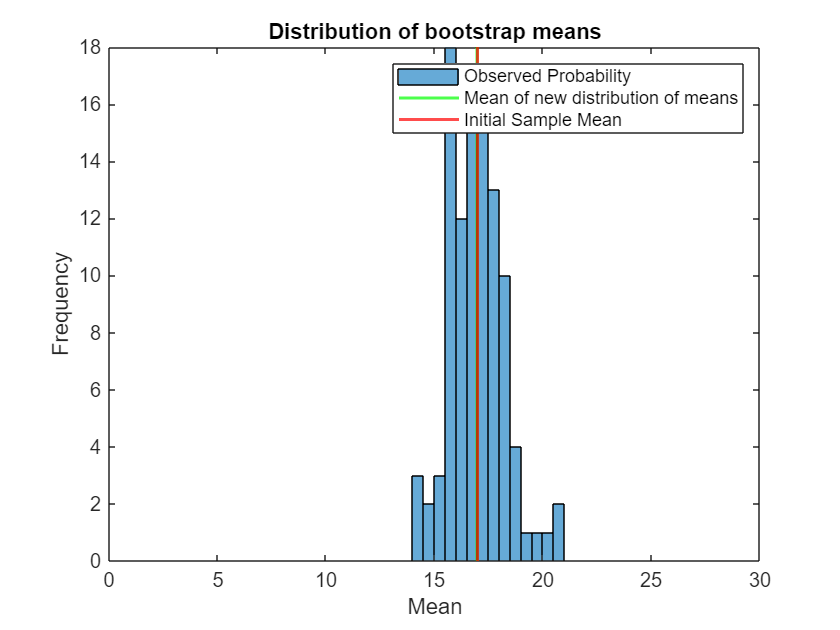

histogram(newMeans,K, DisplayName="Observed Probability",BinWidth=0.5)
xline(mean(newMeans), "green", "LineWidth",1.5, DisplayName="Mean of new distribution of means")
xlabel("Mean"), ylabel("Frequency"),
hold on, xline(mean(initialSample), "red", "LineWidth",1.5, DisplayName="Initial Sample Mean")
legend, hold off, title("Distribution of bootstrap means")
xlim([0 30])

It is clear that the mean of the bootstrap distributions means is close to the initial sample mean (red line and green line).  In other words we can confidentially say that the initial sample mean represent well enough the population mean. 

### A small step toward the Central Limit Theorem

When we have resampled with replacement the intial sample, the bootstraps samples had  796 observations each, just like the initial sample. However, we want to experiment what happens to the distributions of bootstraps means if we resample the initial observations with different sample sample size.

Use the drop down menu to change the value n. Note how the variance of the bootstraps means changes accordingly. 

Note that we have used the same bootstrp MATLAB funcion but this time with the custom `customBootstraps` function to compute the bootstraps means. 

We observe that the more the sample size is big the more the distribution of the bootstrap means  tends to be more normally distributed. 

n = 790; 
newMeans = bootstrp(K,@customBootstraps,initialSample,n); 
disp("Sample Size:" + n +": variance of bootstraps means: "+var(newMeans))

Sample Size:790: variance of bootstraps means: 4.3941


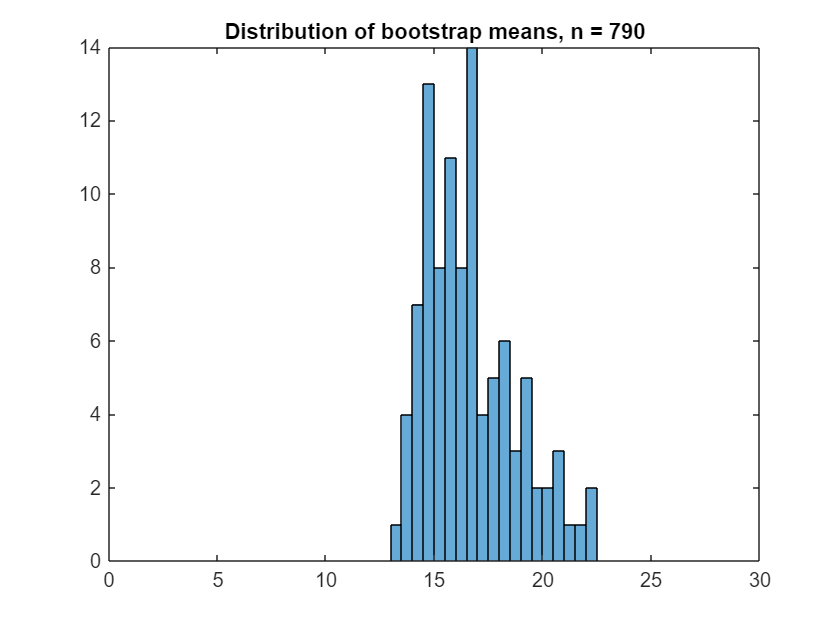

histogram(newMeans,K,BinWidth=0.5), xlim([0 30])
title("Distribution of bootstrap means, n = " +n)


function subSamplesMeans = customBootstraps(initlaSample, n)
    randomDraw = randi(796,[1, n]); 
    subSample = initlaSample(randomDraw); 
    subSamplesMeans = mean(subSample); 
end